%Run with good images
tp_Img = 1; % choose one image [1-100]
ImgFoldername = ['Group_1_CA']; % choose an CA or nCA group folder to proceed
ITest = imread(['logistic_model_Validation images\',ImgFoldername,'\' ,int2str(tp_Img) '.png']);

%Run with corner case images
% ITest = imread(['logistic_model_Corner case images_example\Noise coupled.png']);


% imtool(ITest,[]);

roidep1 = 200;
roidep2 = 500;
roidep3 = 800;

Iroi1 = ITest(roidep1:roidep2,:);
Iroi2 = ITest(roidep2+1:roidep3,:);


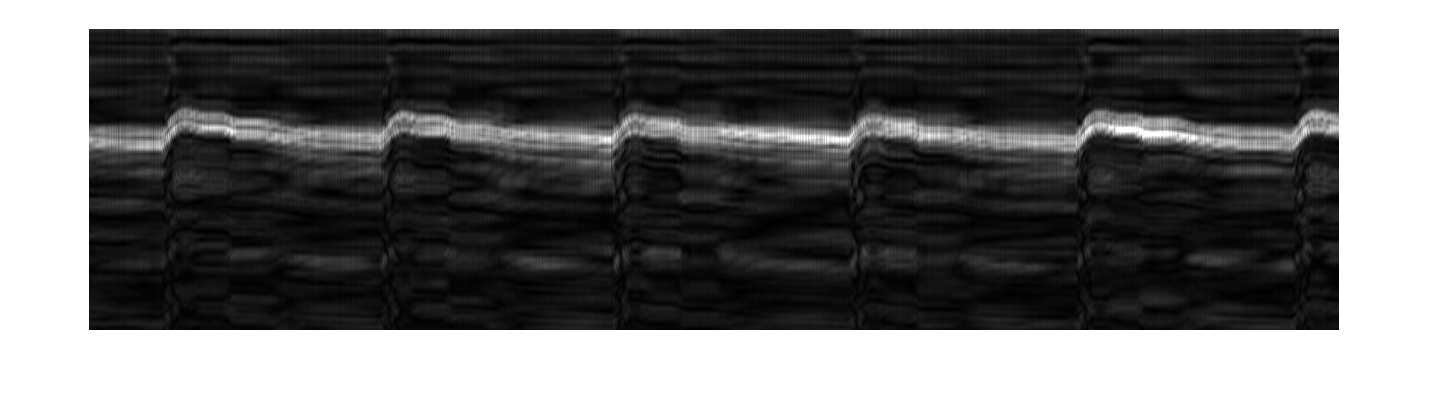

% ROI 1-anterior wall
imshow(Iroi1,[]);

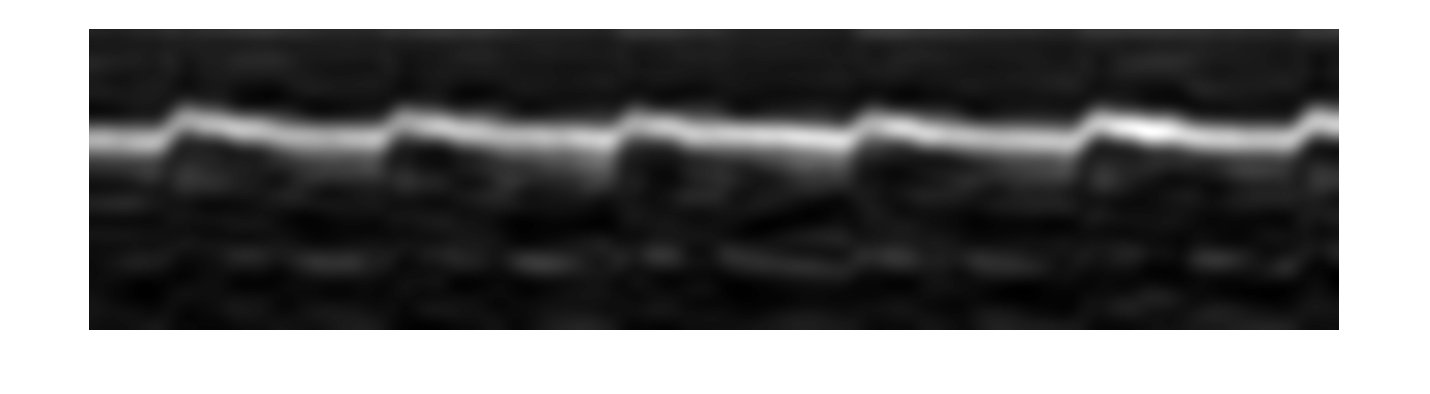

IroiGauss1 = imgaussfilt(Iroi1,8,'Padding','symmetric'); % Gaussion standard deviation: 8
imshow(IroiGauss1,[]);

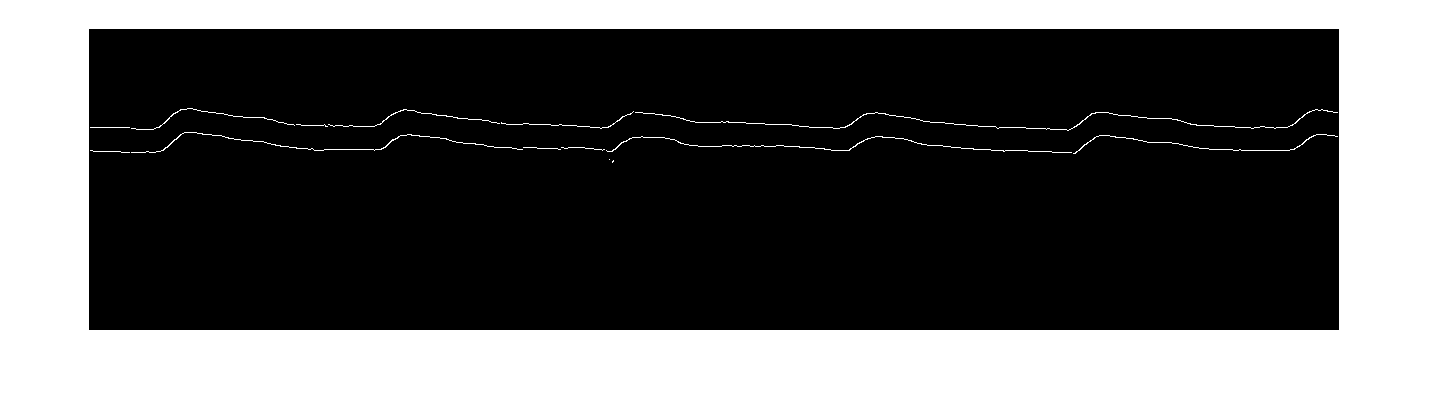

Ibound1 = edge(IroiGauss1,'Canny',0.35); % Edge detection intensity threshold: 0.35 

imshow(Ibound1,[]);

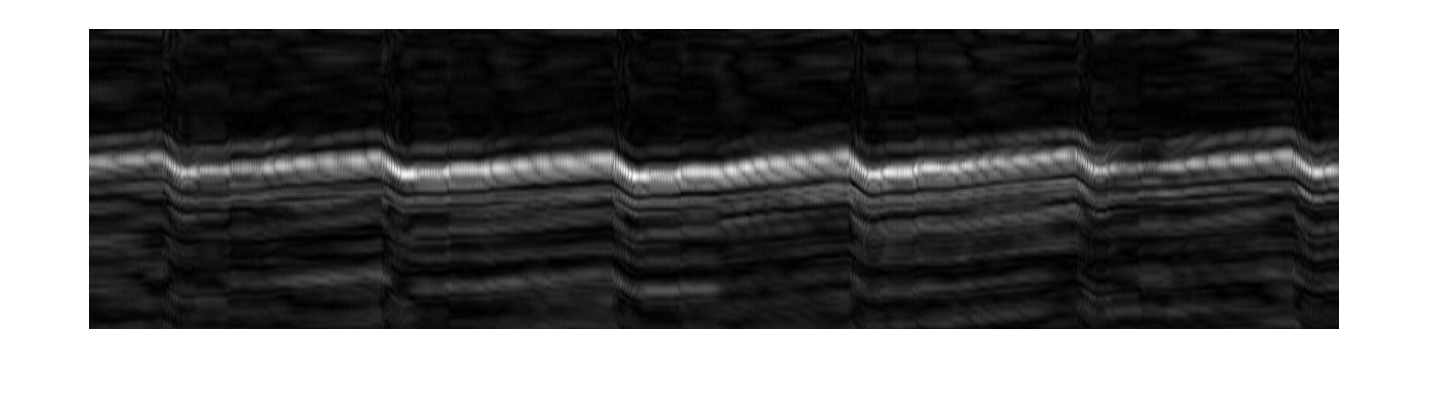

% ROI 2-posterior wall
imshow(Iroi2,[]);

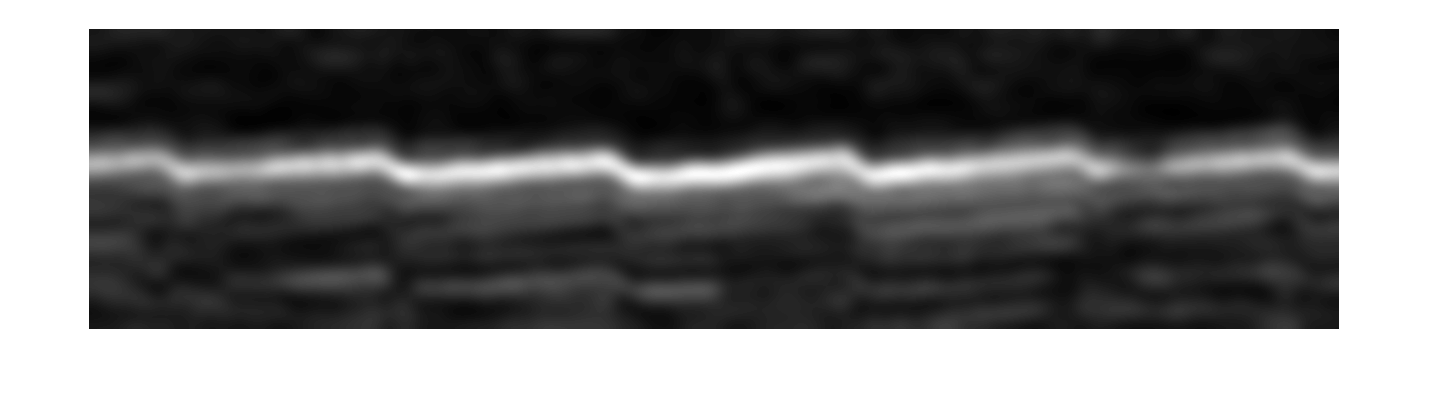

IroiGauss2 = imgaussfilt(Iroi2,8,'Padding','symmetric'); % Gaussion standard deviation: 8
imshow(IroiGauss2,[]);

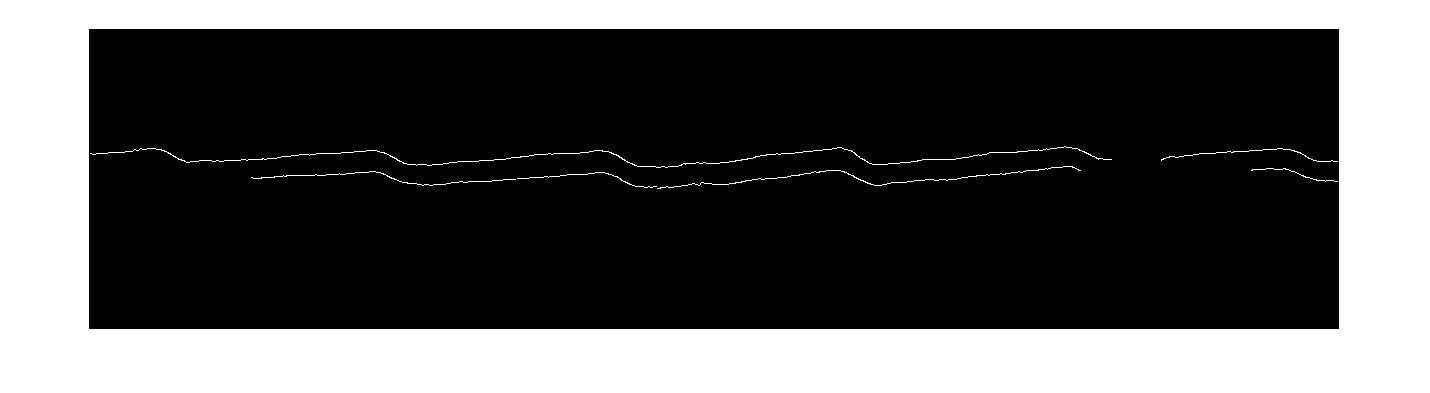

Ibound2 = edge(IroiGauss2,'Canny',0.6); % Edge detection intensity threshold: 0.6 

imshow(Ibound2,[]);

%Recognition

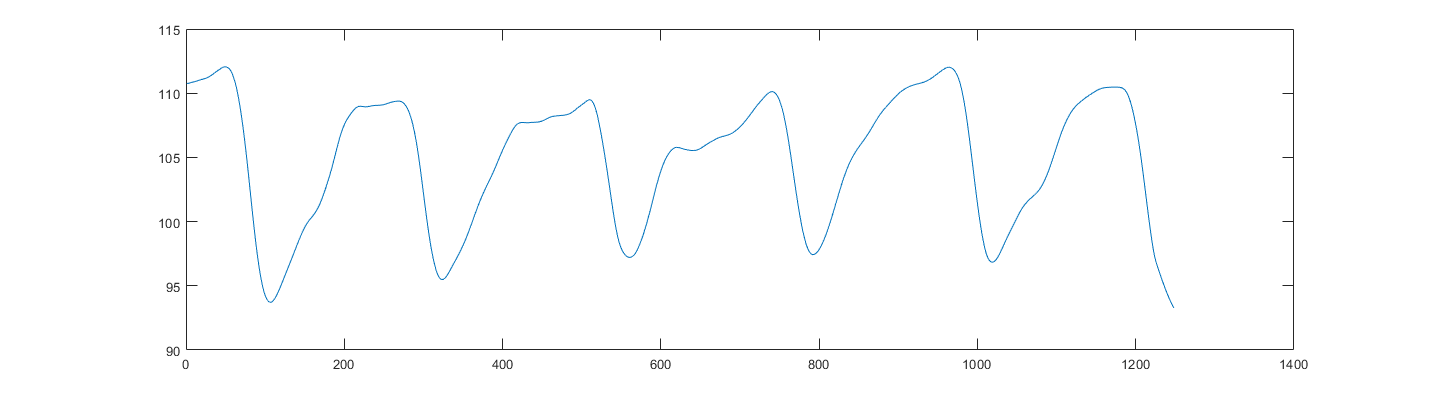

for tp = 1:1250
    AntWall(tp) = mean(find(Ibound1(:,tp),4));
    PostWall(tp) = mean(find(Ibound2(:,tp),4));
    
end

AntWall=smooth(AntWall, 50);
PostWall=smooth(PostWall, 50);

if sum(isnan(AntWall)) > 250 || sum(isnan(AntWall)) > 250
%     IResult(tp_Img) = 0;
    disp('Bad recognition')
else
    
    AntWall(isnan(AntWall)) = 0;
    PostWall(isnan(PostWall)) = 0;
    
    AntWall = smooth(AntWall(2:end-1));
    PostWall = smooth(PostWall(2:end-1));
    
    AntWallFFT = abs(fft(AntWall));
    PostWallFFT = abs(fft(PostWall));
    
    if sum(AntWallFFT(4:10)) > 2e4 || sum(PostWallFFT(4:10)) > 2e4
%         IResult(tp_Img) = 1;
    else
%         IResult(tp_Img) = 0;
    end
end
% end

%IResult


plot(AntWall) % (2:end-1)

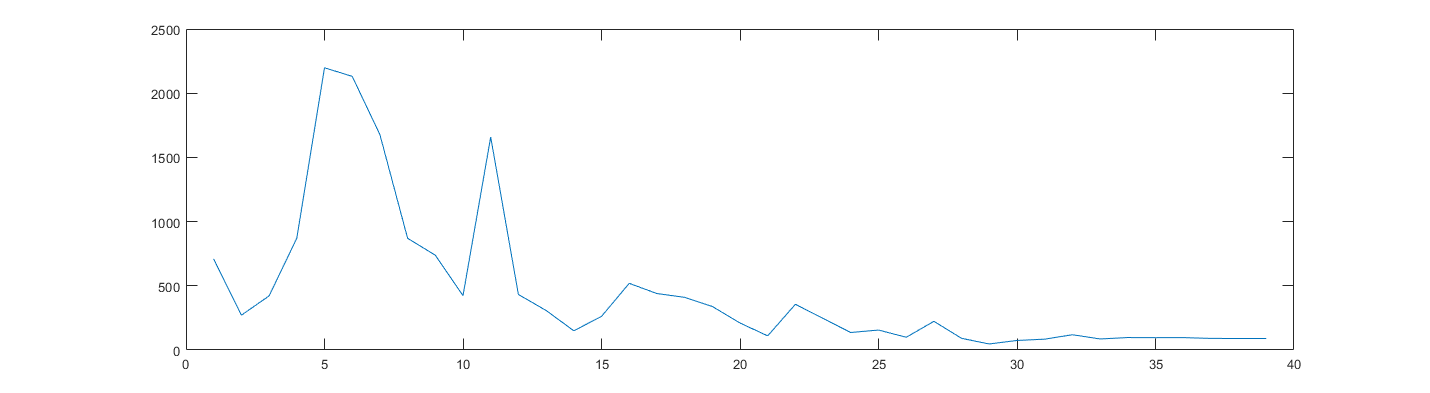

plot(AntWallFFT(2:40))

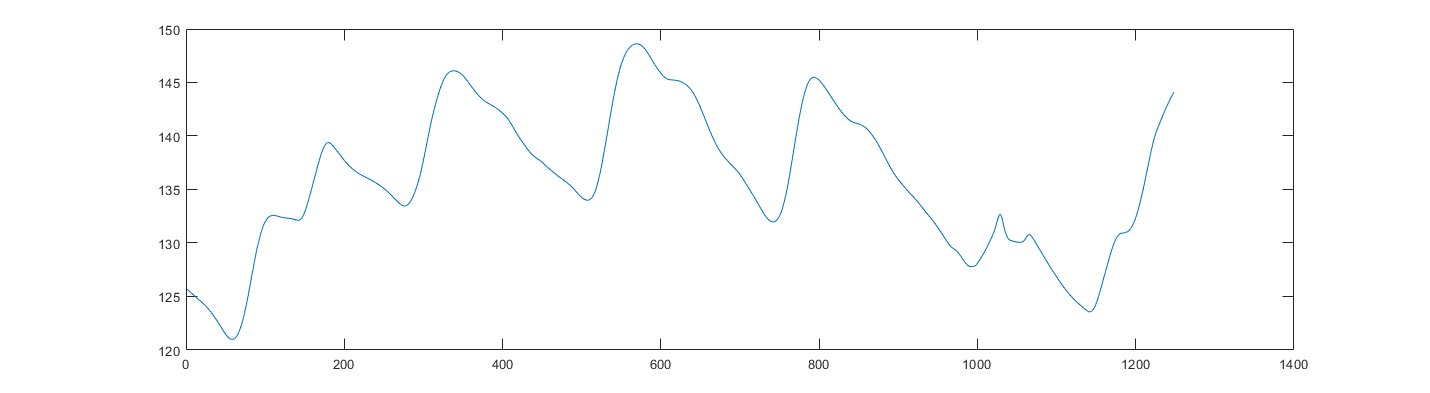

plot(PostWall)

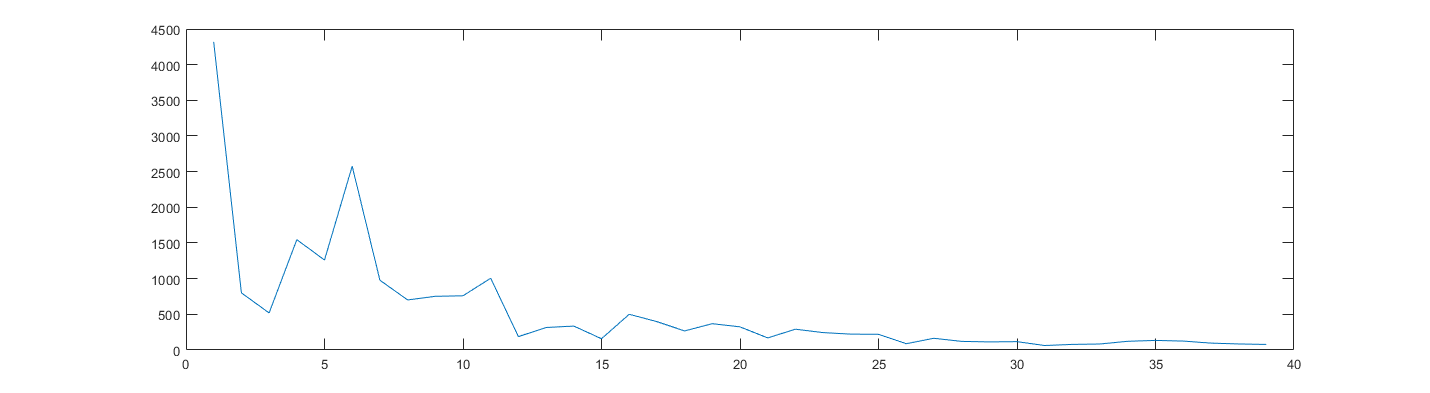

plot(PostWallFFT(2:40))

sum(AntWallFFT(4:10));
sum(PostWallFFT(4:10));

%Classifier

[maximum1, index1]=max(AntWallFFT(2:40));
[maximum2, index2]=max(AntWallFFT(2:40));
index1

index1 = 5

index2

index2 = 5

if (1<index1) & (index1<5) & (1<index2) & (index2<5) 
    CApossibility=1;
else
    CApossibility=0;
end

Result=['CA possibility = ',num2str(CApossibility)] 

Result = 'CA possibility = 0'